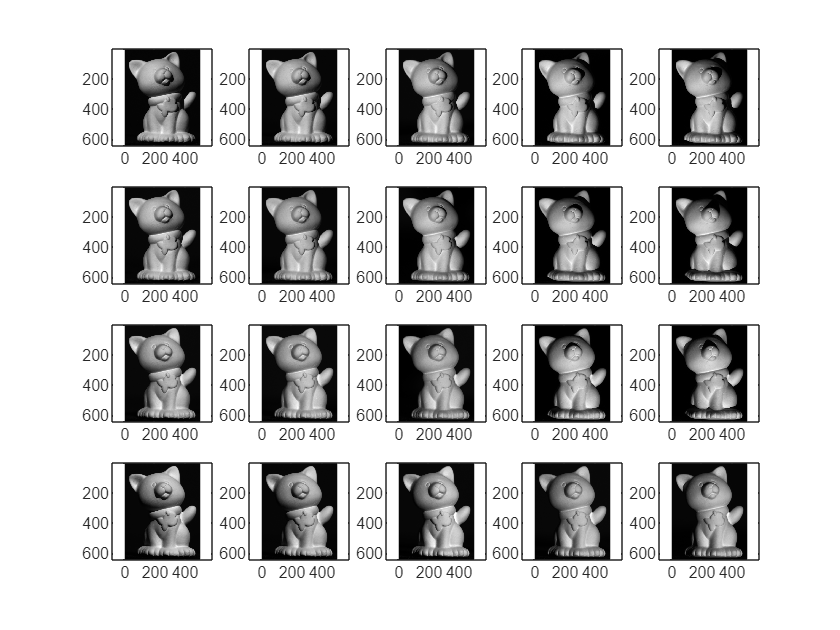

num_images = 20;
images = cell(num_images, 1);
for i = 1:num_images
    s = int2str(i);
    if i < 10
        s = "0" + s;
    end
    images{i} = imread("PSData/cat/Objects/Image_" + s + ".png");

    subplot(4, 5, i);
    imagesc(images{i});
    colormap gray;
    axis equal;
end

sz = size(images{1});

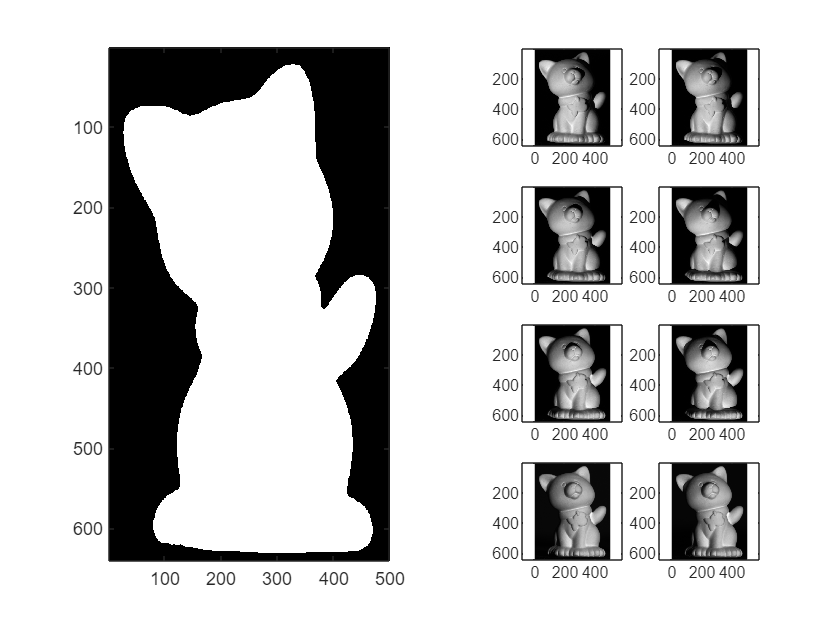

mask = zeros(sz);
threshold = 40;
for i = 1:num_images
    mask = mask | images{i} > threshold;
end
subplot(1, 2, 1);
imagesc(mask);
colormap gray;

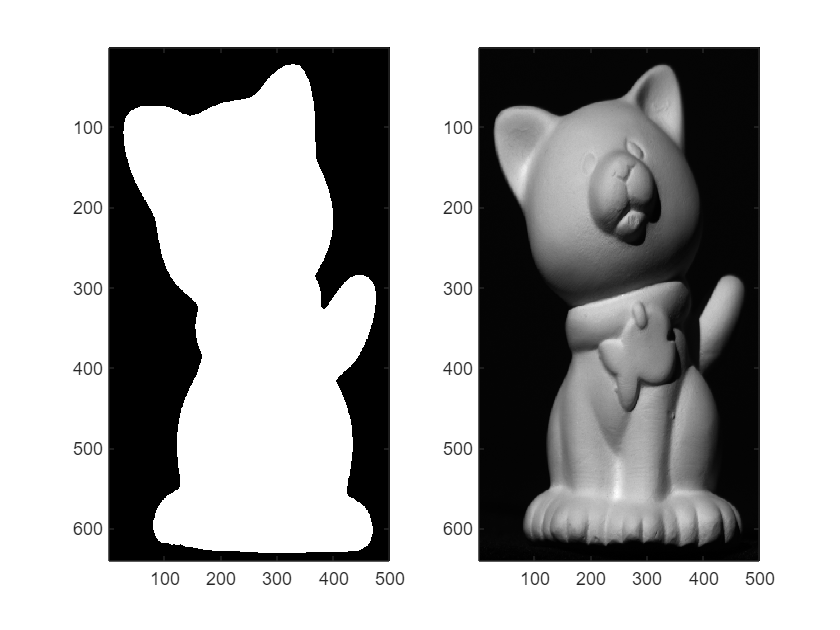

subplot(1, 2, 2);
imagesc(images{1});
colormap gray;

p = nnz(mask);
I = zeros(p, num_images);
for i = 1:num_images
    I(:,i) = images{i}(mask);
end

% [U, Sigma, V] = svd(I, 'econ');
% V = V';
% U_prime = U(:, 1:3);
% Sigma_prime = Sigma(1:3, 1:3);
% V_prime = V(1:3, :);
% 
% Sigma_root = Sigma_prime .^ 0.5;
% S_hat = U_prime * Sigma_root;
% L_hat = Sigma_root * V_prime;
% norm(S_hat * L_hat - I, 'fro') / norm(I, "fro")

% Handle shadows
take_rows = true(p, 1);
take_cols = true(num_images, 1);

shadowed = false(p, num_images);
for i = 1:num_images
    shadowed(:, i) = I(:, i) <= threshold;
end

while take_rows' * shadowed * take_cols > 0
    if nnz(take_rows) > nnz(take_cols)
        num_remove = nnz(take_rows) - nnz(take_cols);

        num_shadows_row = shadowed * take_cols;
        [~, inds] = sort(num_shadows_row, "descend");
        num_remove = min(num_remove, nnz(num_shadows_row));
        take_rows(inds(1:num_remove)) = false;

        % [~, ind_remove] = max(shadowed * take_cols);
        % take_rows(ind_remove) = false;
    else
        [~, ind_remove] = max(shadowed' * take_rows);
        take_cols(ind_remove) = false;
    end

end

I_tilde = I(take_rows, take_cols);
[U, Sigma, V] = svd(I_tilde, "econ");
V = V';
U_prime = U(:, 1:3);
Sigma_prime = Sigma(1:3, 1:3);
V_prime = V(1:3, :);

Sigma_root = Sigma_prime .^ 0.5;
S_tilde = U_prime * Sigma_root;
L_tilde = Sigma_root * V_prime;
norm(S_tilde * L_tilde - I_tilde, 'fro') / norm(I_tilde, "fro")

ans = 0.0155

S_hat = zeros(p, 3);
S_hat(take_rows, :) = S_tilde;
L_hat = zeros(3, num_images);
L_hat(:, take_cols) = L_tilde;

illuminated = ~shadowed;
while nnz(take_rows) < p || nnz(take_cols) < num_images

    if nnz(take_cols) == num_images
        % Calculate the rest of the surface normals
        for i = 1:p
            if take_rows(i)
                continue
            end
            S_hat(i, :) = L_hat(:, illuminated(i, :))' \ I(i, illuminated(i, :))';
        end

        take_rows = true(p, 1);

    elseif nnz(take_rows) < nnz(take_cols)
        % Calculate nnz(take_cols) - nnz(take_rows) more surface normals
        num_add = nnz(take_cols) - nnz(take_rows);
        num_illuminated_row = illuminated * take_cols;

        [~, inds] = sort(num_illuminated_row, "descend");
        for i = inds
            if take_rows(i)
                continue
            end

            num_add = num_add - 1;
            take_rows(i) = true;
            
            include_data = illuminated(i, :) & take_cols';
            S_hat(i, :) = L_hat(:, include_data)' \ I(i, include_data)';

            if num_add == 0
                break
            end
        end
    else
        % Calculate nnz(take_rows) - nnz(take_cols) + 1 light source
        num_add = nnz(take_rows) - nnz(take_cols) + 1;
        num_illuminated_col = take_rows' * illuminated;

        [~, inds] = sort(num_illuminated_col, "descend");
        for i = inds
            if take_cols(i)
                continue
            end

            num_add = num_add - 1;
            take_cols(i) = true;

            include_data = illuminated(:, i) & take_rows;
            L_hat(:, i) = S_hat(include_data, :) \ I(include_data, i);

            if num_add == 0
                break
            end
        end
    end
end

I_calc = S_hat * L_hat;
norm(illuminated .* (I_calc - I), "fro") / norm(illuminated .* I)

ans = 0.0217

% Upgrade
coeff = [S_hat(:, 1) .^ 2, 2 * S_hat(:, 1) .* S_hat(:, 2), 2 * S_hat(:, 1) .* S_hat(:, 3), ...
    S_hat(:, 2) .^ 2, 2 * S_hat(:, 2) .* S_hat(:, 3), S_hat(:, 3) .^ 2];

B_nums = coeff \ ones(p, 1);
B = [B_nums(1), B_nums(2), B_nums(3)
    B_nums(2), B_nums(4), B_nums(5)
    B_nums(3), B_nums(5), B_nums(6)];

[W, Pi, ~] = svd(B);
A = W * Pi .^ 0.5;
S = S_hat * A;
mean(vecnorm(S, 2, 2))

ans = 0.8807

L = A \ L_hat;

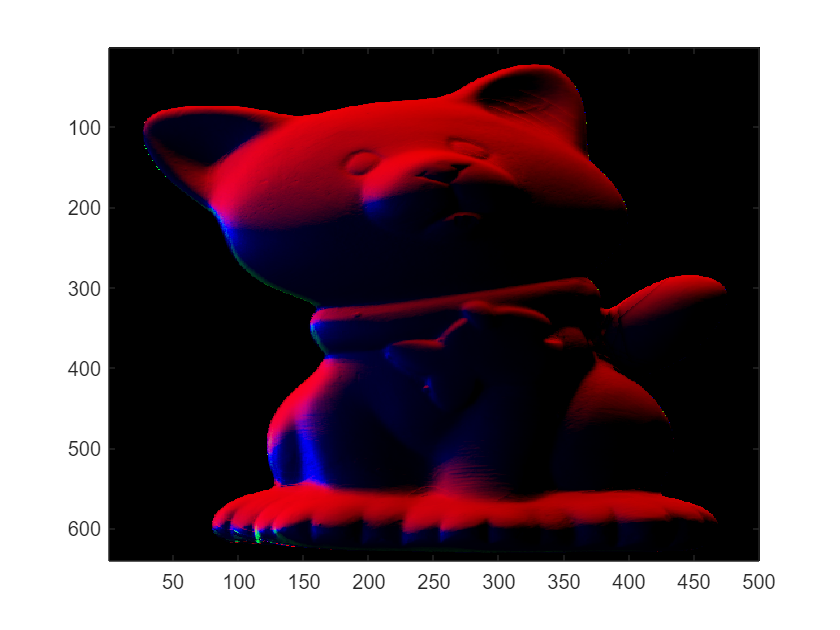

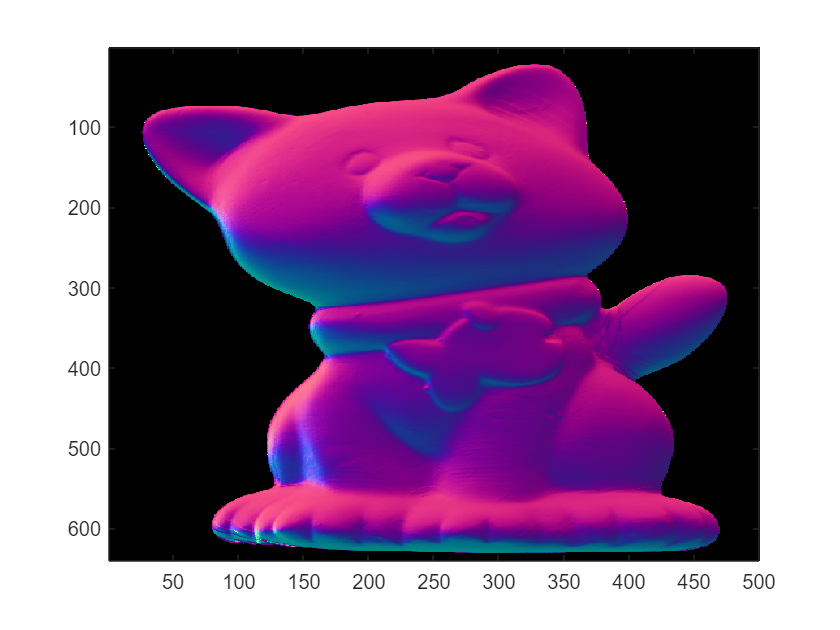

normal_image = visualize_normals(S, mask, sz);

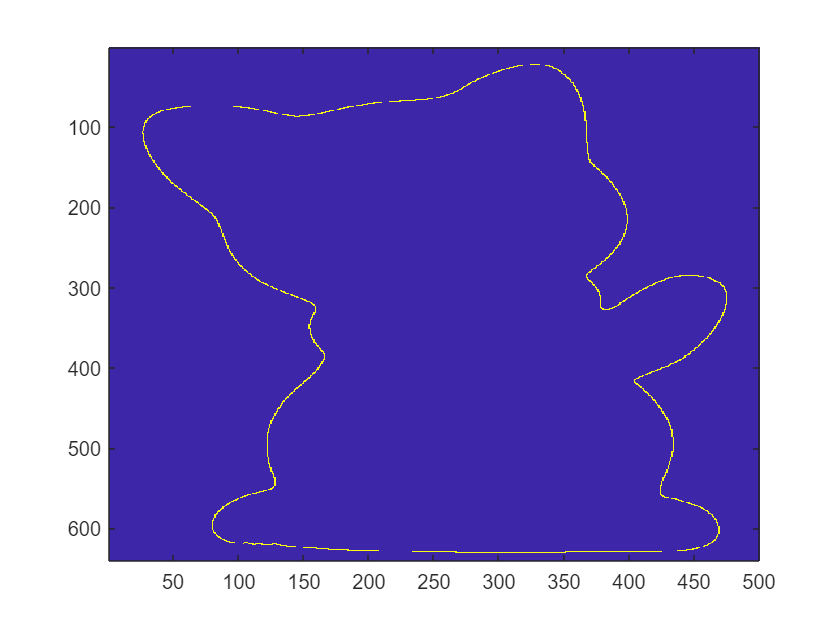

% Second upgrade, z axis
mask_border = conv2(mask, ones(3), "same");
mask_border = (mask_border < 9) & mask;
imagesc(mask_border);

% DLT
M = normal_image(cat(3, mask_border, mask_border, mask_border));
M = reshape(M, [nnz(mask_border), 3]);
[~, ~, V] = svd(M);
R3 = V(:, 3);
if sum(S * R3, "all") < 0
    R3 = -R3;
end

% Make R
R2 = cross(R3, [1;0;0]);
if norm(R2) < 1e-3
    R2 = cross(R3, [0;1;0]);
end
R2 = normalize(R2, "norm");
R1 = cross(R2, R3);

R = [R1, R2, R3];
S = S * R;
L = R' * L;

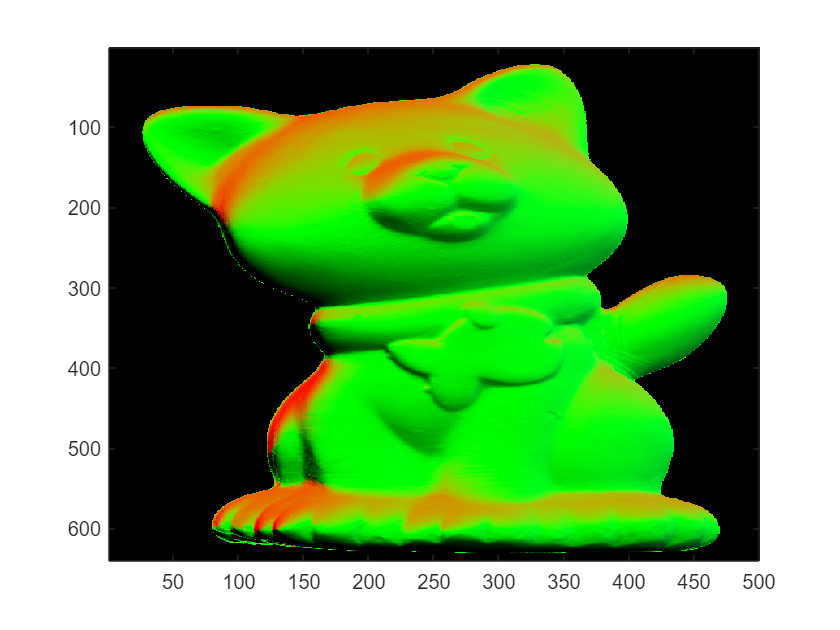

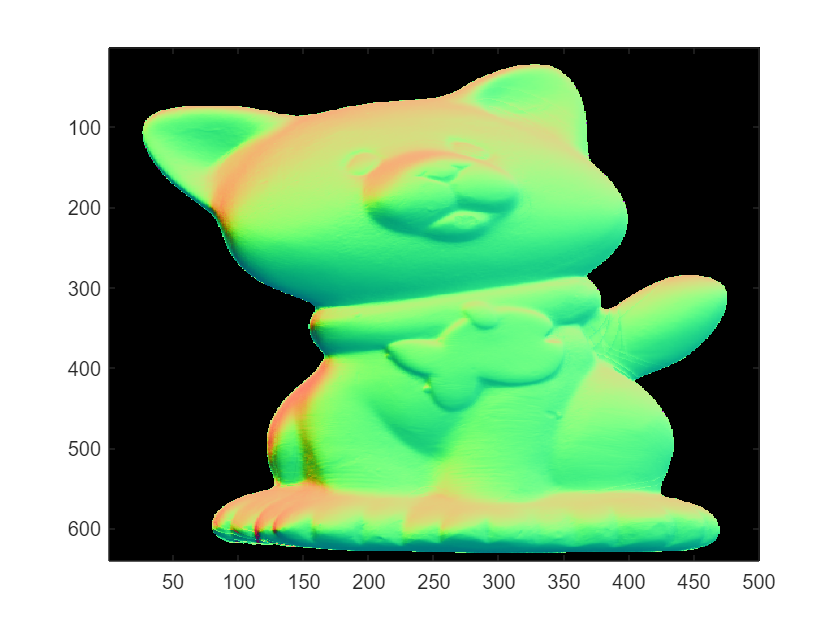

normal_image = visualize_normals(S, mask, sz);

% Third upgrade, x and y axis
rightmost_column = find(sum(mask_border, 1), 1, "last");
sections = bwlabel(mask_border(:, rightmost_column), 4);
unique_sections = unique(sections);
section_sizes = histc(sections, unique_sections);
[~, max_section] = max(section_sizes);
component_indices = find(sections == max_section);
center = round(mean(component_indices));

right_normal = normalize(reshape(normal_image(center, rightmost_column, 1:2), [2 1]), "norm");
radians = 0;
if right_normal(1) < 0
    radians = pi;
    right_normal = -right_normal;
end
radians = radians - asin(right_normal(2));

R = [
    cos(-radians), -sin(-radians), 0
    sin(-radians), cos(-radians), 0
    0, 0, 1
];

S = S * R;
L = R' * L;

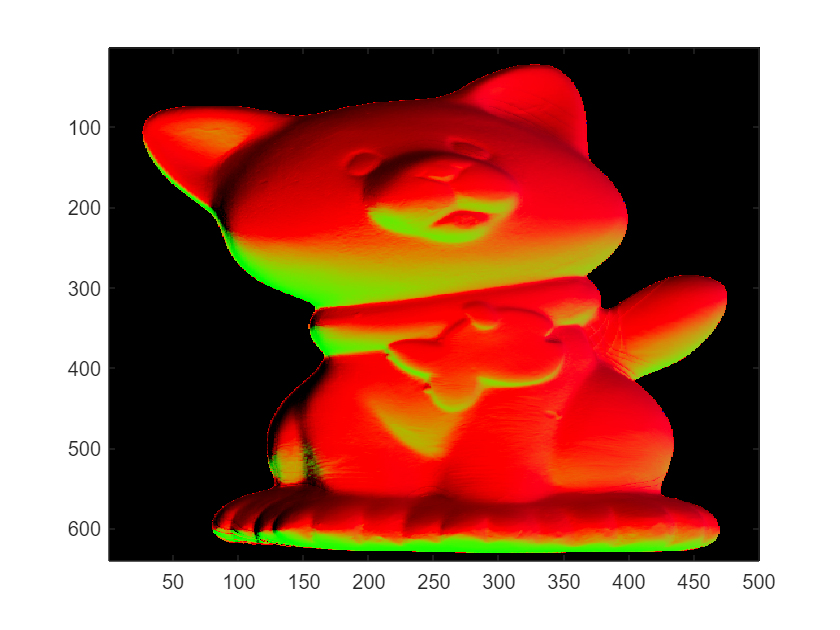

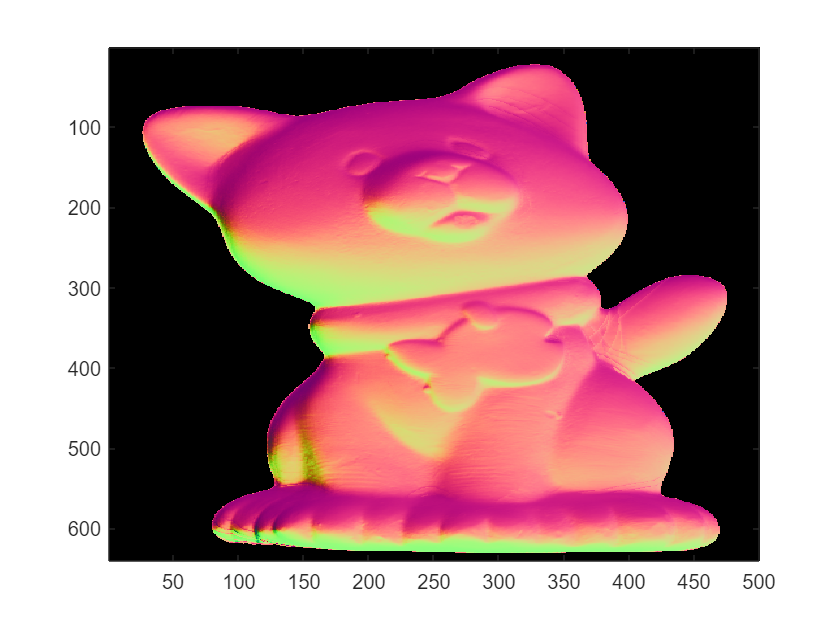

normal_image = visualize_normals(S, mask, sz);

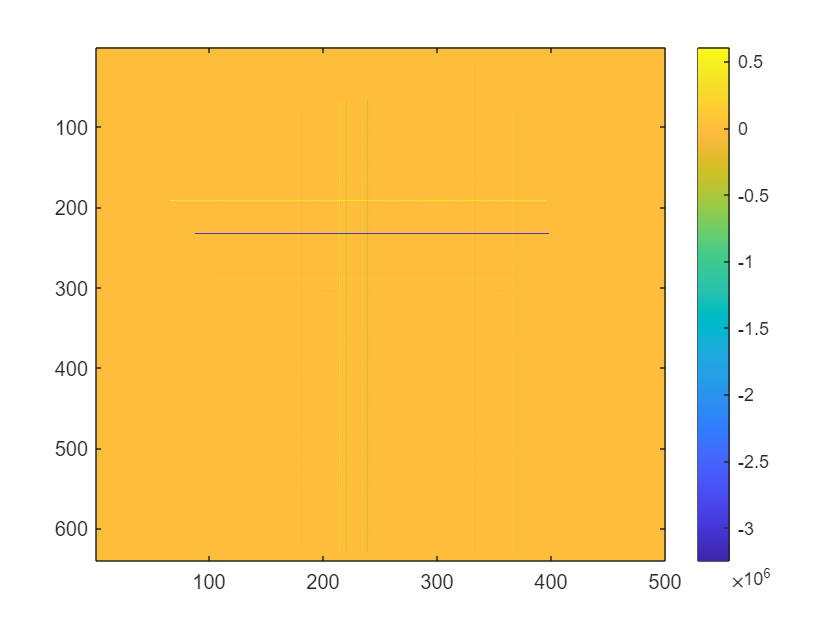

% Naive surface integration
depths = zeros(sz);
for i = 0:3
    depths = depths - rotate_n_and_integrate(sz, mask, normal_image, i);
end
depths = depths / 4;

figure
imagesc(depths);
colorbar

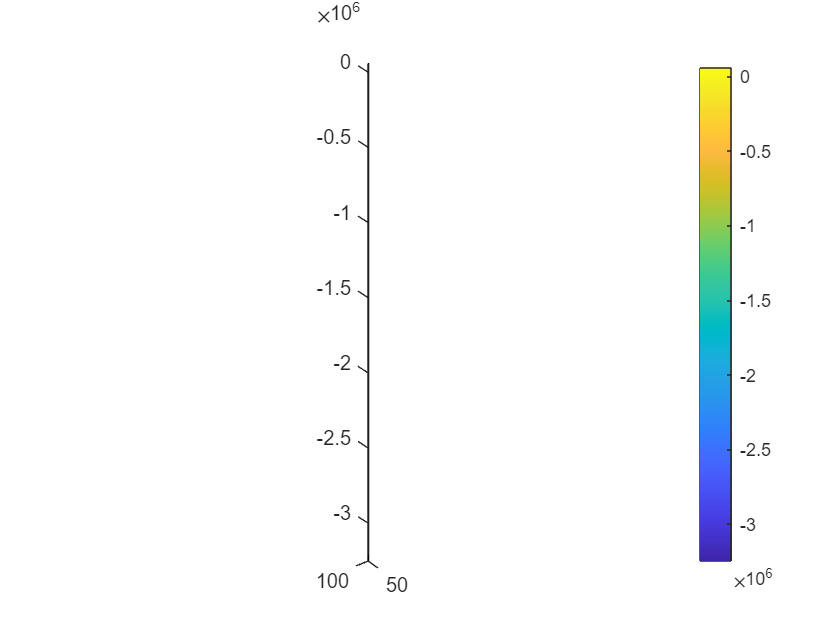

surf(depths(1:2:end, 1:2:end));
colorbar;
axis equal;

% Improve integration
grads = -normal_image(:,:,1:2) ./ (normal_image(:,:,3) + (normal_image(:,:,3) == 0));
for it = 1:100
    next_depths = zeros(sz);

    next_depths(:, 2:end)   = next_depths(:, 2:end)   + depths(:, 1:end-1) + (grads(:, 1:end-1, 1) + grads(:, 2:end, 1)) ./ 2;
    next_depths(:, 1:end-1) = next_depths(:, 1:end-1) + depths(:, 2:end)   - (grads(:, 2:end, 1)   + grads(:, 1:end-1, 1)) ./ 2;

    next_depths(2:end, :)   = next_depths(2:end, :)   + depths(1:end-1, :) + (grads(1:end-1, :, 2) + grads(2:end, :, 2)) ./ 2;
    next_depths(1:end-1, :) = next_depths(1:end-1, :) + depths(2:end, :)   - (grads(2:end, :, 2)   + grads(1:end-1, :, 2)) ./ 2;

    depths = next_depths .* mask / 4;
end

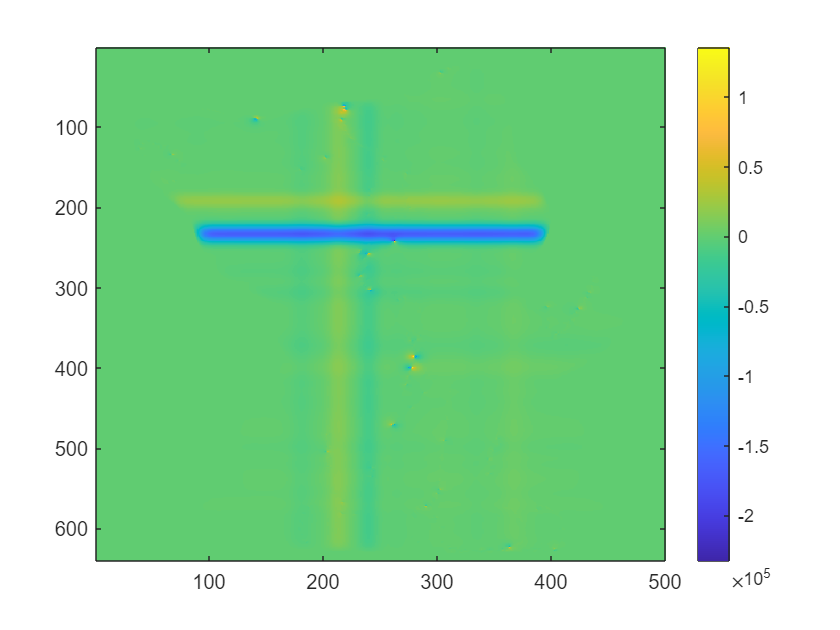

figure
imagesc(depths);
colorbar

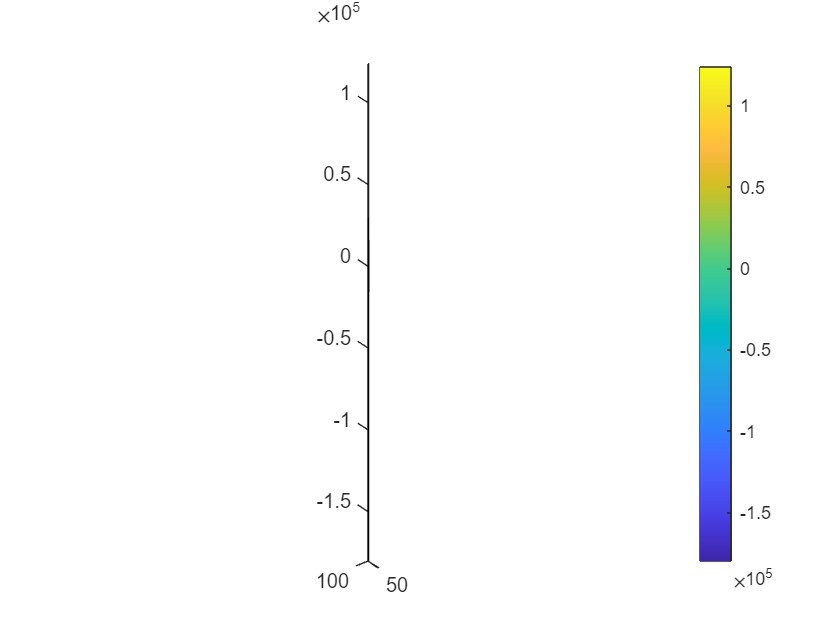


figure
surf(depths(1:2:end, 1:2:end));
colorbar;
axis equal;

function normal_image = visualize_normals(S, mask, sz)
    % Visualize
    normals = normalize(S, 2, "norm");
    normal_image = zeros(sz(1), sz(2), 3);
    
    mask_3d = cat(3, mask, mask, mask);
    normal_image(mask_3d) = normals;
    normal_colors = (normal_image / 2 + 0.5) .* mask_3d;
    
    figure
    imagesc(normal_image);
    figure
    imagesc(normal_colors);
end
function image = rotate_image_cw(image)
    image = permute(image(end:-1:1, :, :), [2 1 3]);
end
function image = rotate_image_ccw(image)
    image = permute(image(:, end:-1:1, :), [2 1 3]);
end
function depths = integrate_x_pos(sz, mask, normal_image)
    depths = zeros(sz);
    for row = 1:sz(1)
       for col = 2:sz(2)
           if mask(row, col) && mask(row, col-1)
               n = normalize(normal_image(row, col-1, :) + normal_image(row, col, :), 3, 'norm');
               depths(row, col) = depths(row, col-1) + n(1) / (n(3) + (n(3) == 0));
           end
       end
    end
end
function depths = rotate_n_and_integrate(sz, mask, normal_image, n)
    for i = 1:n
        normal_image = rotate_image_cw(normal_image);
        normal_image = normal_image(:, :, [2 1 3]);
        mask = rotate_image_cw(mask);
        sz = [sz(2), sz(1)];
    end
    depths = integrate_x_pos(sz, mask, normal_image);
    for i = 1:n
        depths = rotate_image_ccw(depths);
    end
end